clear all;
close all;
clc;
delta1 = input('Enter the Pass Band Ripple: ');
delta2 = input('Enter the Stop Band Ripple: ');
wp = input('Enter the Digital Pass Band Edge Frequency: ');
ws = input('Enter the Digital Stop Band Edge Frequency: ');
T = input('Enter the Sampling Time Period in Seconds: ');
omegap = (2/T)*tan(wp/2);
omegas = (2/T)*tan(ws/2); 
den = 2*log10(omegas/omegap);
delta = ((1/(delta2^2))-1);
epsi  = ((1/(delta1^2))-1);
num = log10(delta/epsi);
N = ceil(num/den);

disp('1: LPF, 2: HPF, 3: BPF, 4: BSF');

1: LPF, 2: HPF, 3: BPF, 4: BSF


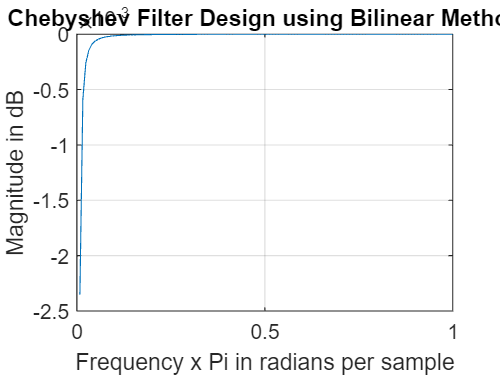

type = input('Enter the type of the filter you want to design: ');

switch type
    case 1
        rp = -20*log10(1/delta1);
        [n, wc] = cheb1ord(omegap, omegas, rp, -20*log10(delta2), 's');
        [b, a] = cheby1(n, rp, wc, 's');
    case 2
        rp = -20*log10(1/delta1);
        [n, wc] = cheb1ord(omegap, omegas, rp, -20*log10(delta2), 's');
        [b, a] = cheby1(n, rp, wc, 'high');
    case 3
        rp = -20*log10(1/delta1);
        rs = -20*log10(delta2);
        [n, wc] = cheb1ord(omegap, omegas, rp, rs, 's');
        wc1=0.2
        wc2=0.4
        [b, a] = cheby1(n, rp, [wc1,wc2], 'bandpass');
    case 4
        rp = -20*log10(1/delta1);
        rs = -20*log10(delta2);
        [n, wc] = cheb1ord(omegap, omegas, rp, rs, 's');
        wc1=0.2
        wc2=0.4
        [b, a] = cheby1(n, rp, [wc1,wc2], 'stop');
    otherwise
        disp('The Type Entered is not a valid filter');
end
[H, W] = freqz(b, a, linspace(0, pi, 128));
plot(W/pi, 20*log10(abs(H)));
grid on;
xlabel('Frequency x Pi in radians per sample');
ylabel('Magnitude in dB');
title('Chebyshev Filter Design using Bilinear Method');